# DICOM image windowing

This live script demonstrates the use of [windowing](https://radiopaedia.org/articles/windowing-ct?lang=us) in DICOM images with the MATLAB DICOM functions.

## What is windowing and why we need it?

Medical images have a large number of gray levels. It is not uncommon for them to have four thousand or more levels.

Most computer screens, on the other hand, can display only 256 levels of gray. Even if a computer screen could display more gray levels, the human eye would not be able to distinguish them.

To get around these problems, medical images are displayed using windows, i.e. instead of mapping the large grayscale in the image linearly into the 256 gray levels supported by computer screens, specific ranges of the image grayscale are emphasized.

[This article](https://towardsdatascience.com/a-matter-of-grayscale-understanding-dicom-windows-1b44344d92bd) has a good explanation of the problem and demonstrations of how windowing solves it.

The next sections in the live script demonstrate windowing with the [MATLAB DICOM functions](https://www.mathworks.com/company/newsletters/articles/accessing-data-in-dicom-files.html) and [MATLAB image processing functions](https://www.mathworks.com/help/images/).

### Limitations

Medical imaging is a complex topic. This live script makes several simplifications when manipulating the images. In particular, it assumes that the images use the [Hounsfield Unit](https://www.ncbi.nlm.nih.gov/books/NBK547721/) (HU) for grasycale, limiting the examples to CT images.

## DICOM image selection

The live script folder includes sample images from the [RSNA STR Pulmonary Embolism Detection Kaggle competition](https://www.kaggle.com/c/rsna-str-pulmonary-embolism-detection/data). 

Pick one of the images from the list to analyze.

fileName = "012c12fe09c3.dcm";

## Image information

Read the DICOM information and the image.

info = dicominfo(fileName);
image = dicomread(fileName);

Display some pieces of information about the image.

fprintf("Color type = %s", info.ColorType)

Color type = grayscale

fprintf("Width = %d, height = %d pixels", info.Width, info.Height)

Width = 512, height = 512 pixels

fprintf("Modality (acquiring equipment): %s", info.Modality)

Modality (acquiring equipment): CT

**NOTE**: from this point on, the code assumes that the image is a CT in grayscale. It will fail miserable if the image is of a different modality.

if info.Modality ~= "CT"
    disp("The code is prepared to handle CT images only")
    return
end

## Rescaling

The image stored in a DICOM file does not necessarily use the actual pixel values. They may be manipulated to fit into a non-negative range, for example, or values specific to the device that acquired the image ([source 1](https://blog.kitware.com/dicom-rescale-intercept-rescale-slope-and-itk/#:~:text=Rescale%20intercept%2C%20(0028%7C1052,to%20their%20in%20memory%20representation.&text=A%20different%20range%20of%20values,on%20disk%20versus%20in%20memory.), [source 2](https://stackoverflow.com/questions/8756096/window-width-and-center-calculation-of-dicom-image/8765366#8765366)).

We need to rescale the image back to the [Hounsfield Unit](https://www.ncbi.nlm.nih.gov/books/NBK547721/) range.

**NOTE**: this code assumes that scale is linear. It does not support [lookup table rescaling](http://dicom.nema.org/medical/Dicom/2018d/output/chtml/part03/sect_C.11.html).

% If the image has only non-negative values, it is read as uint16
% Need to convert to a data type that support negative values first
rescaledImage = int16(image);
% No error checking - assume that slope and intercept exist
rescaledImage = rescaledImage * info.RescaleSlope + info.RescaleIntercept;

fprintf("Rescale slope = %d, intercept = %d", ...
    info.RescaleSlope, info.RescaleIntercept)

Rescale slope = 1, intercept = -1024

fprintf("Before rescaling: max pixel value = %d, min = %d", ...
    max(image(:)), min(image(:)))

Before rescaling: max pixel value = 3154, min = -2000

fprintf("After rescaling:  max pixel value = %d, min = %d", ...
    max(rescaledImage(:)), min(rescaledImage(:)))

After rescaling:  max pixel value = 2130, min = -3024

## Image histogram

The image histogram shows how the gray levels are distributed.

It is common for DICOM images to use dark colors (usually the lowest pixel value) as background. A histogram will show a large spike for that value, followed by significantly smaller bars for the other values.

This imbalance in the distribution may make it difficult to analyze the histogram. Switch to a log scale to see a more useful histogram.

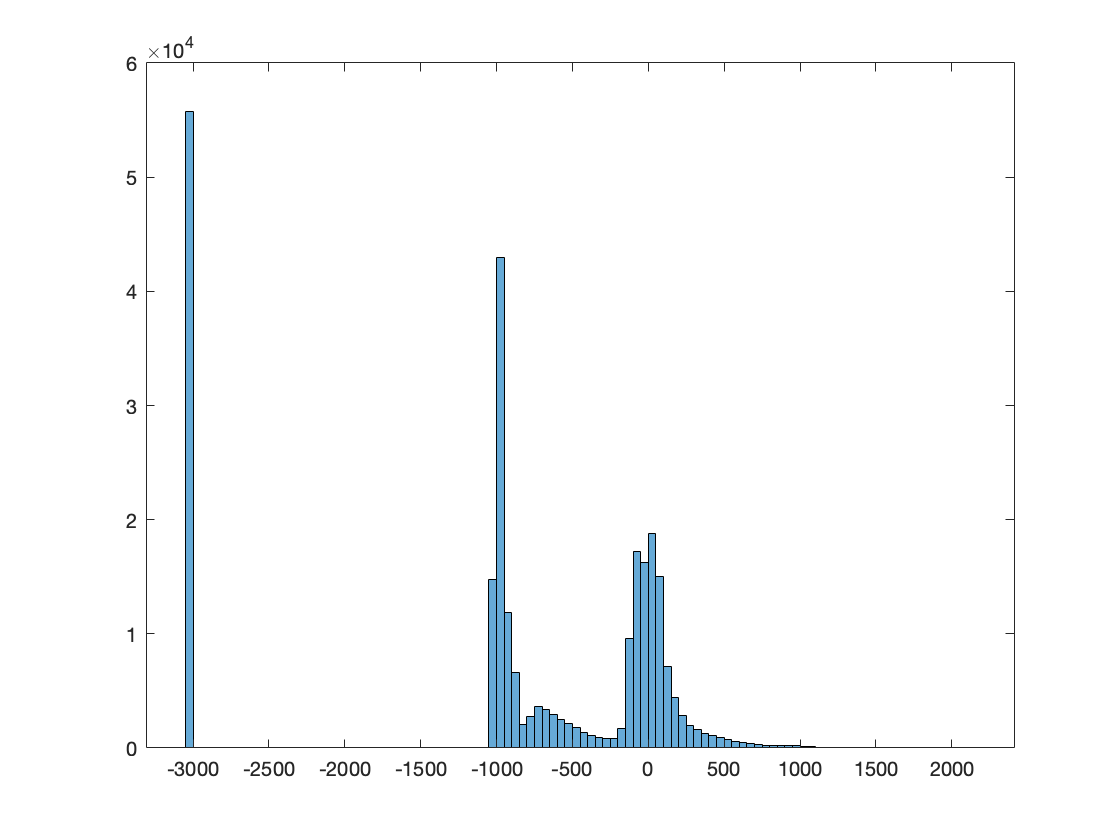

useLogScale = false;
figure
histogram(rescaledImage) % looks better than imhist imho

if useLogScale
    set(gca, 'YScale', 'log')
end

## Image without adjustment

This section shows the image without performing any adjustment.

Simply showing the image results in a linear mapping of the large grayscale to the 256 scale supported by computer screens. The result is usually not pleasant.

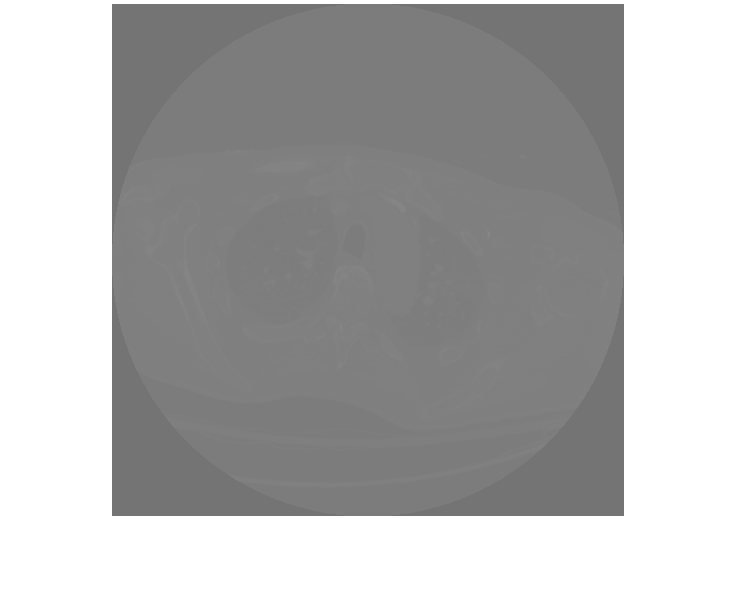

figure
imshow(rescaledImage)

We can do better than that by specifying an [empty DisplayRange](https://www.mathworks.com/help/images/ref/imshow.html#bvmnrxi-1-DisplayRange). MATLAB evenly spreads the image's grayscale into the 256 levels of gray. This is equivalent to not attempting to adjust the contrast and to not emphasize any feature of the image. It is a simpler, linear mapping of the image scale into the 256 gray levels of the computer screen.

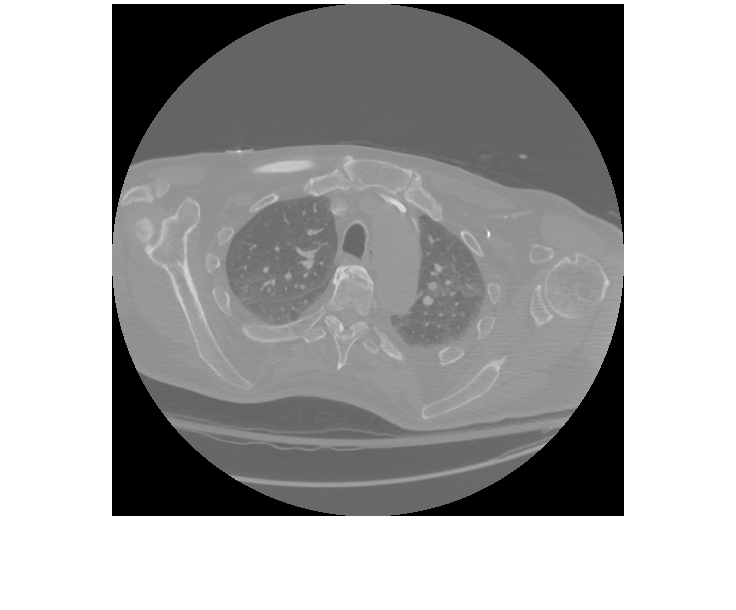

figure
imshow(rescaledImage, [])

## Image with automatic contrast adjustment

Instead of evenly spreading out the gray levels with DisplayRange, we can adjust the contrast with the [contrast-enhancing functions](https://www.mathworks.com/help/images/contrast-enhancement-techniques.html). Contrast enhancement does not treat all pixels the same. It changes the gray level distribution (it changes the image's histogram), resulting in a more balanced image.

There are several contrast-enhancing functions. The result depends on the distribution of the grayscale of the original image. Because medical images (CT in particular) have large dark areas, a histogram-based adjustment (histeq) tends to perform well (compare to the other contrast-adjusting functions).

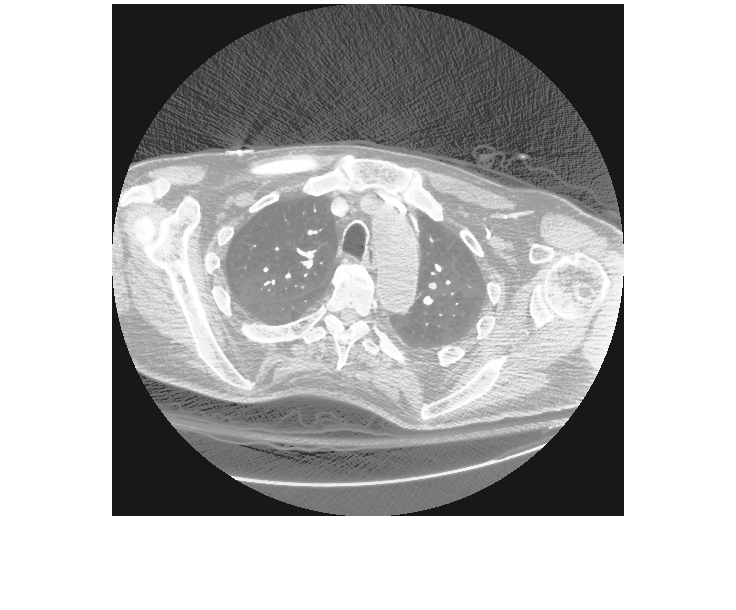

enhancement = "histeq";
figure
imshow(feval(enhancement, rescaledImage))

## Image with windowing

Although automatic contrast enhancement improves the display of the image, it does not have any information about how the image was acquired and what it represents.

This is where windowing comes into the picture (pun intended, as bad as it may be...).

### How windowing works

With windowing we specify the range we want to enhance using two parameters, the window center and the window width. These two values create a range that is mapped to the 256 levels of gray supported by computer screens.

For example, with center set to 1,000 and width set to 400, we would map the range [800, 1200] to the 256 levels of gray. Values below that range are mapped to zero and values above that range are mapped to 256.

### But what values to pick for center and width?

DICOM files may store a window center and width. They are chosen based on what the image is being used for (what pathology is being analyzed, for example), what part of the body was scanned, among other factors.

Displaying the image with the recommended window usually results in better contrast than automatic contrast adjustment. Compare the image below with the automatic contrast adjustment above. It is an example of "having information about the data beats even smart generic algorithms".

**NOTE**: Another simplification: the code uses only the first window. DICOM files may store several windows.

Using window center 40 and width 350

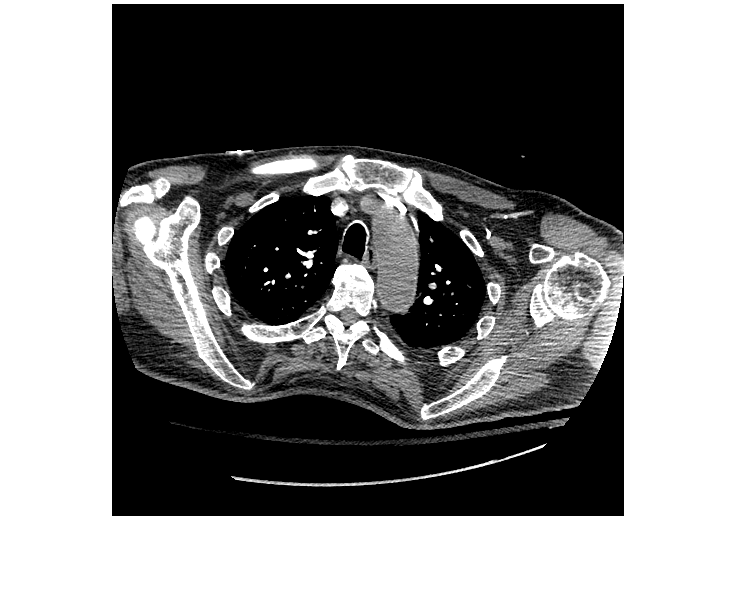

if isfield(info, "WindowCenter") && isfield(info, "WindowWidth")
    minPixelValue = info.WindowCenter - info.WindowWidth / 2;
    maxPixelValue = info.WindowCenter + info.WindowWidth / 2;
    fprintf("Using window center %d and width %d", ...
        info.WindowCenter(1), info.WindowWidth(1))
    figure
    imshow(rescaledImage, [minPixelValue(1) maxPixelValue(1)])
else
    fprintf("The image does not have a window center and width")
end

## Customized center and width 

Changing the window center and width emphasizes different aspects of the image.

The [Hounsfield unit scale](https://en.wikipedia.org/wiki/Hounsfield_scale) (HU) describes what ranges are used to highlight specific items in the image. For example, the range [20, 45] highlights the kidney, [-700 -600] highlights the lungs, and the range [0 45] highlights abscess/pus (bacterial infection).

Select a range in the dropdown below to see the effect in the image visualization.

Note that the predefined range are approximations and some ranges overlap. The exact ranges depend on how the image was acquired (equipment, contrasting agents, patient position, etc.). For example, selecting a range for an organ that is not present in the image results in a not-so-useful window.

range = "+300 +400"

range = "+300 +400"

% Convert the range string to numerical values
minMax = sscanf(range, "%d %d")

minMax =    300
   400


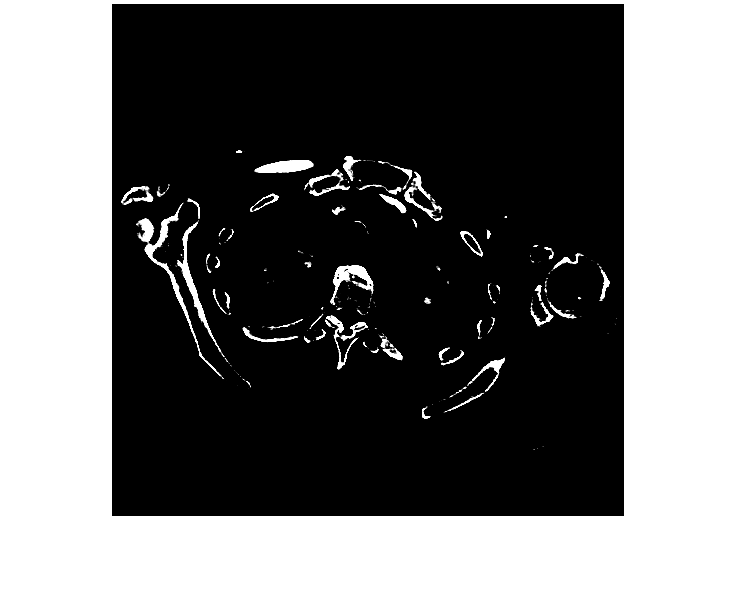

figure
imshow(rescaledImage, minMax)

## Links to useful resources

- [A Matter of Grayscale: Understanding Dicom Windows | by Amrit Virdee](https://towardsdatascience.com/a-matter-of-grayscale-understanding-dicom-windows-1b44344d92bd): explains the concept and application of windowing in detail.

- [A Practical Introduction to CT](https://www.youtube.com/watch?v=VnpqylFYtqI): a video that explains how to work with CT images, showing how windowing is used to analyze different types of issues and other artifacts in the image.

- [fastai/60_medical.imaging.ipynb at master · fastai/fastai · GitHub](https://github.com/fastai/fastai/blob/master/nbs/60_medical.imaging.ipynb): Jupyter notebook demonstrating how to process medical images. 

- [How to set the display range for this medical DICOM images](https://stackoverflow.com/q/42096890/336802) (Stackoverflow)